1. Set up grids

An=100 %grid num

An = 100

Agrid=linspace(0,15,An) %asset grid

Agrid =          0    0.1515    0.3030    0.4545    0.6061    0.7576    0.9091    1.0606    1.2121    1.3636    1.5152    1.6667    1.8182    1.9697    2.1212    2.2727    2.4242    2.5758    2.7273    2.8788    3.0303    3.1818    3.3333    3.4848    3.6364    3.7879    3.9394    4.0909    4.2424    4.3939    4.5455    4.6970    4.8485    5.0000    5.1515    5.3030    5.4545    5.6061    5.7576    5.9091    6.0606    6.2121    6.3636    6.5152    6.6667    6.8182    6.9697    7.1212    7.2727    7.4242


Ygrid=[-0.5 0.0 0.5] %y grid

Ygrid =    -0.5000         0    0.5000


Value=zeros(An,3)

Value =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


policy=zeros(An,3)

policy =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


T=[0.9 0.08 0.02; 0.15 0.7 0.15 ; 0.05 0.15 0.8]

T =     0.9000    0.0800    0.0200
    0.1500    0.7000    0.1500
    0.0500    0.1500    0.8000


beta=0.95

beta = 0.9500

r=0.035

r = 0.0350

2. Find value function and policy function

err=3.0

err = 3

while err>10^-5
    Newvalue=zeros(An,3);
    for j=1:3
        for i=1:An
            income=(1+r)*Agrid(i)+exp(Ygrid(j));
            pcons=max(1e-7,income-Agrid); %to prevent log minus value
            candvalue=log(pcons)+beta*T(j,:)*Value'; %This is vector of RHS with all possible a'
            [maxval,argmax]=max(candvalue);
            Newvalue(i,j)=maxval;
            policy(i,j)=argmax;
        end
    end
    err=max(abs(Newvalue-Value),[],'all')
    Value(:)=Newvalue(:)
end

err = 2.8434

Value =    -0.5000         0    0.5000
   -0.2700    0.1457    0.5909
   -0.0832    0.2728    0.6741
    0.0742    0.3856    0.7510
    0.2101    0.4869    0.8224
    0.3298    0.5789    0.8890
    0.4366    0.6632    0.9515
    0.5331    0.7409    1.0103
    0.6212    0.8129    1.0658
    0.7021    0.8802    1.1184


err = 1.5402

Value =    -0.9180         0    0.8606
   -0.6880    0.1479    0.9602
   -0.4717    0.2928    1.0537
   -0.2860    0.4204    1.1440
   -0.1093    0.5465    1.2289
    0.0464    0.6588    1.3115
    0.1958    0.7703    1.3893
    0.3299    0.8708    1.4654
    0.4594    0.9708    1.5373
    0.5772    1.0617    1.6078


err = 1.1109

Value =    -1.2685   -0.0082    1.1217
   -1.0386    0.1424    1.2273
   -0.8219    0.2882    1.3265
   -0.6173    0.4325    1.4254
   -0.4328    0.5612    1.5194
   -0.2569    0.6868    1.6092
   -0.0890    0.8118    1.6982
    0.0651    0.9244    1.7833
    0.2131    1.0351    1.8652
    0.3556    1.1451    1.9463


err = 0.8568

Value =    -1.5639   -0.0264    1.3073
   -1.3339    0.1269    1.4173
   -1.1170    0.2741    1.5262
   -0.9119    0.4185    1.6283
   -0.7172    0.5621    1.7269
   -0.5339    0.6919    1.8246
   -0.3589    0.8177    1.9212
   -0.1917    0.9422    2.0124
   -0.0314    1.0659    2.1013
    0.1211    1.1788    2.1892


err = 0.6823

Value =    -1.8143   -0.0541    1.4429
   -1.5843    0.1015    1.5547
   -1.3671    0.2512    1.6645
   -1.1614    0.3962    1.7727
   -0.9663    0.5397    1.8776
   -0.7803    0.6815    1.9808
   -0.5981    0.8124    2.0792
   -0.4240    0.9392    2.1768
   -0.2574    1.0633    2.2728
   -0.0977    1.1867    2.3661


err = 0.5541

Value =    -2.0279   -0.0889    1.5328
   -1.7980    0.0686    1.6494
   -1.5805    0.2200    1.7627
   -1.3744    0.3664    1.8741
   -1.1786    0.5099    1.9831
   -0.9921    0.6526    2.0887
   -0.8099    0.7926    2.1927
   -0.6325    0.9241    2.2947
   -0.4593    1.0516    2.3942
   -0.2934    1.1759    2.4922


err = 0.4551

Value =    -2.2115   -0.1297    1.5929
   -1.9816    0.0297    1.7121
   -1.7638    0.1828    1.8286
   -1.5573    0.3306    1.9419
   -1.3611    0.4747    2.0535
   -1.1739    0.6176    2.1621
   -0.9917    0.7586    2.2702
   -0.8138    0.8969    2.3757
   -0.6398    1.0286    2.4792
   -0.4707    1.1567    2.5812


err = 0.3769

Value =    -2.3704   -0.1744    1.6289
   -2.1405   -0.0133    1.7499
   -1.9226    0.1413    1.8684
   -1.7157    0.2905    1.9841
   -1.5189    0.4353    2.0989
   -1.3312    0.5782    2.2111
   -1.1490    0.7198    2.3207
   -0.9705    0.8595    2.4285
   -0.7963    0.9963    2.5357
   -0.6261    1.1278    2.6401


err = 0.3141

Value =    -2.5090   -0.2216    1.6457
   -2.2791   -0.0592    1.7686
   -2.0610    0.0968    1.8898
   -1.8538    0.2472    2.0083
   -1.6565    0.3931    2.1243
   -1.4683    0.5361    2.2385
   -1.2861    0.6782    2.3516
   -1.1070    0.8185    2.4616
   -0.9328    0.9566    2.5697
   -0.7620    1.0921    2.6768


err = 0.2631

Value =    -2.6308   -0.2704    1.6509
   -2.4008   -0.1068    1.7743
   -2.1826    0.0505    1.8965
   -1.9751    0.2022    2.0165
   -1.7775    0.3491    2.1353
   -1.5887    0.4924    2.2513
   -1.4065    0.6346    2.3653
   -1.2269    0.7757    2.4779
   -1.0526    0.9146    2.5887
   -0.8812    1.0511    2.6978


err = 0.2207

Value =    -2.7385   -0.3195    1.6450
   -2.5086   -0.1550    1.7700
   -2.2902    0.0034    1.8929
   -2.0825    0.1561    2.0143
   -1.8845    0.3041    2.1338
   -1.6953    0.4480    2.2519
   -1.5130    0.5902    2.3680
   -1.3330    0.7314    2.4824
   -1.1586    0.8713    2.5946
   -0.9867    1.0088    2.7055


err = 0.1854

Value =    -2.8345   -0.3683    1.6317
   -2.6045   -0.2031    1.7574
   -2.3861   -0.0438    1.8810
   -2.1782    0.1099    2.0034
   -1.9798    0.2588    2.1244
   -1.7902    0.4034    2.2439
   -1.6080    0.5456    2.3613
   -1.4274    0.6871    2.4772
   -1.2530    0.8274    2.5912
   -1.0806    0.9658    2.7035


err = 0.1566

Value =    -2.9204   -0.4163    1.6122
   -2.6905   -0.2505    1.7393
   -2.4720   -0.0906    1.8641
   -2.2639    0.0640    1.9866
   -2.0653    0.2137    2.1085
   -1.8753    0.3591    2.2292
   -1.6931    0.5015    2.3480
   -1.5121    0.6430    2.4651
   -1.3377    0.7838    2.5804
   -1.1648    0.9226    2.6943


err = 0.1315

Value =    -2.9980   -0.4633    1.5889
   -2.7680   -0.2968    1.7167
   -2.5495   -0.1363    1.8426
   -2.3413    0.0188    1.9662
   -2.1425    0.1692    2.0883
   -1.9522    0.3154    2.2097
   -1.7697    0.4581    2.3295
   -1.5886    0.5998    2.4480
   -1.4141    0.7406    2.5644
   -1.2408    0.8800    2.6791


err = 0.1110

Value =    -3.0683   -0.5089    1.5632
   -2.8383   -0.3419    1.6914
   -2.6197   -0.1808    1.8179
   -2.4114   -0.0252    1.9424
   -2.2124    0.1258    2.0655
   -2.0219    0.2726    2.1869
   -1.8391    0.4158    2.3076
   -1.6580    0.5578    2.4267
   -1.4832    0.6986    2.5441
   -1.3098    0.8381    2.6603


err = 0.0930

Value =    -3.1324   -0.5529    1.5355
   -2.9024   -0.3855    1.6645
   -2.6837   -0.2240    1.7911
   -2.4753   -0.0678    1.9164
   -2.2762    0.0837    2.0401
   -2.0854    0.2310    2.1620
   -1.9024    0.3746    2.2829
   -1.7212    0.5169    2.4032
   -1.5462    0.6577    2.5215
   -1.3727    0.7975    2.6383


err = 0.0789

Value =    -3.1910   -0.5952    1.5067
   -2.9611   -0.4275    1.6362
   -2.7423   -0.2656    1.7633
   -2.5338   -0.1089    1.8887
   -2.3345    0.0430    2.0134
   -2.1436    0.1907    2.1361
   -1.9603    0.3346    2.2573
   -1.7792    0.4774    2.3777
   -1.6039    0.6182    2.4968
   -1.4304    0.7581    2.6145


err = 0.0653

Value =    -3.2449   -0.6358    1.4770
   -3.0150   -0.4678    1.6073
   -2.7962   -0.3056    1.7351
   -2.5876   -0.1486    1.8608
   -2.3882    0.0038    1.9856
   -2.1971    0.1519    2.1089
   -2.0136    0.2962    2.2308
   -1.8325    0.4392    2.3512
   -1.6569    0.5800    2.4710
   -1.4834    0.7200    2.5892


err = 0.0544

Value =    -3.2947   -0.6748    1.4476
   -3.0647   -0.5064    1.5781
   -2.8459   -0.3439    1.7063
   -2.6373   -0.1866    1.8327
   -2.4378   -0.0338    1.9575
   -2.2466    0.1146    2.0813
   -2.0628    0.2592    2.2037
   -1.8817    0.4024    2.3245
   -1.7059    0.5432    2.4444
   -1.5324    0.6834    2.5634


err = 0.0460

Value =    -3.3407   -0.7119    1.4184
   -3.1108   -0.5433    1.5490
   -2.8919   -0.3805    1.6777
   -2.6832   -0.2230    1.8045
   -2.4836   -0.0699    1.9297
   -2.2923    0.0788    2.0535
   -2.1084    0.2238    2.1765
   -1.9273    0.3672    2.2978
   -1.7514    0.5080    2.4177
   -1.5778    0.6482    2.5371


err = 0.0428

Value =    -3.3835   -0.7474    1.3896
   -3.1535   -0.5786    1.5205
   -2.9347   -0.4155    1.6493
   -2.7259   -0.2577    1.7766
   -2.5262   -0.1045    1.9022
   -2.3348    0.0446    2.0261
   -2.1508    0.1898    2.1494
   -1.9697    0.3334    2.2711
   -1.7936    0.4743    2.3915
   -1.6200    0.6145    2.5109


err = 0.0398

Value =    -3.4233   -0.7811    1.3615
   -3.1933   -0.6122    1.4926
   -2.9745   -0.4489    1.6216
   -2.7656   -0.2909    1.7491
   -2.5659   -0.1374    1.8751
   -2.3744    0.0118    1.9994
   -2.1903    0.1574    2.1226
   -2.0092    0.3011    2.2447
   -1.8329    0.4422    2.3654
   -1.6593    0.5823    2.4848


err = 0.0371

Value =    -3.4604   -0.8132    1.3340
   -3.2304   -0.6441    1.4655
   -3.0116   -0.4808    1.5947
   -2.8027   -0.3225    1.7223
   -2.6029   -0.1688    1.8485
   -2.4113   -0.0194    1.9731
   -2.2271    0.1263    2.0964
   -2.0460    0.2703    2.2188
   -1.8696    0.4115    2.3399
   -1.6959    0.5516    2.4594


err = 0.0347

Value =    -3.4951   -0.8438    1.3073
   -3.2651   -0.6746    1.4391
   -3.0462   -0.5111    1.5685
   -2.8374   -0.3526    1.6962
   -2.6375   -0.1988    1.8227
   -2.4458   -0.0492    1.9476
   -2.2615    0.0967    2.0710
   -2.0804    0.2408    2.1936
   -1.9039    0.3822    2.3149
   -1.7303    0.5224    2.4348


err = 0.0325

Value =    -3.5276   -0.8729    1.2815
   -3.2976   -0.7035    1.4135
   -3.0787   -0.5399    1.5433
   -2.8698   -0.3813    1.6710
   -2.6699   -0.2273    1.7977
   -2.4782   -0.0775    1.9228
   -2.2938    0.0685    2.0465
   -2.1127    0.2127    2.1691
   -1.9361    0.3543    2.2906
   -1.7624    0.4944    2.4108


err = 0.0305

Value =    -3.5581   -0.9005    1.2568
   -3.3281   -0.7310    1.3889
   -3.1092   -0.5673    1.5189
   -2.9003   -0.4086    1.6468
   -2.7003   -0.2545    1.7735
   -2.5085   -0.1045    1.8988
   -2.3241    0.0416    2.0227
   -2.1430    0.1859    2.1453
   -1.9663    0.3277    2.2671
   -1.7926    0.4678    2.3875


err = 0.0286

Value =    -3.5867   -0.9268    1.2330
   -3.3568   -0.7572    1.3652
   -3.1378   -0.5933    1.4954
   -2.9289   -0.4346    1.6235
   -2.7289   -0.2803    1.7502
   -2.5371   -0.1302    1.8757
   -2.3526    0.0160    1.9997
   -2.1715    0.1604    2.1224
   -1.9947    0.3023    2.2444
   -1.8210    0.4425    2.3649


err = 0.0269

Value =    -3.6137   -0.9516    1.2102
   -3.3837   -0.7820    1.3425
   -3.1648   -0.6181    1.4728
   -2.9558   -0.4592    1.6010
   -2.7558   -0.3049    1.7278
   -2.5639   -0.1547    1.8535
   -2.3793   -0.0083    1.9777
   -2.1982    0.1361    2.1005
   -2.0214    0.2782    2.2225
   -1.8477    0.4184    2.3432


err = 0.0253

Value =    -3.6390   -0.9752    1.1884
   -3.4090   -0.8056    1.3207
   -3.1901   -0.6416    1.4511
   -2.9811   -0.4827    1.5795
   -2.7811   -0.3282    1.7064
   -2.5892   -0.1779    1.8321
   -2.4046   -0.0314    1.9564
   -2.2235    0.1131    2.0794
   -2.0466    0.2552    2.2014
   -1.8729    0.3955    2.3223


err = 0.0239

Value =    -3.6629   -0.9976    1.1675
   -3.4329   -0.8281    1.2999
   -3.2140   -0.6639    1.4304
   -3.0050   -0.5049    1.5589
   -2.8049   -0.3504    1.6859
   -2.6130   -0.2000    1.8116
   -2.4283   -0.0534    1.9361
   -2.2472    0.0911    2.0592
   -2.0703    0.2333    2.1812
   -1.8966    0.3736    2.3022


err = 0.0225

Value =    -3.6854   -1.0189    1.1475
   -3.4555   -0.8493    1.2800
   -3.2365   -0.6851    1.4105
   -3.0275   -0.5260    1.5392
   -2.8274   -0.3715    1.6663
   -2.6354   -0.2210    1.7920
   -2.4508   -0.0744    1.9166
   -2.2697    0.0702    2.0398
   -2.0927    0.2125    2.1618
   -1.9190    0.3529    2.2829


err = 0.0213

Value =    -3.7067   -1.0391    1.1285
   -3.4767   -0.8695    1.2610
   -3.2578   -0.7053    1.3915
   -3.0487   -0.5461    1.5203
   -2.8486   -0.3915    1.6475
   -2.6566   -0.2410    1.7733
   -2.4719   -0.0942    1.8979
   -2.2908    0.0504    2.0213
   -2.1139    0.1927    2.1432
   -1.9401    0.3332    2.2645


err = 0.0201

Value =    -3.7267   -1.0583    1.1102
   -3.4968   -0.8887    1.2429
   -3.2778   -0.7244    1.3734
   -3.0688   -0.5652    1.5023
   -2.8687   -0.4105    1.6296
   -2.6767   -0.2600    1.7553
   -2.4920   -0.1132    1.8801
   -2.3109    0.0316    2.0035
   -2.1338    0.1739    2.1256
   -1.9601    0.3144    2.2468


err = 0.0190

Value =    -3.7457   -1.0764    1.0929
   -3.5157   -0.9068    1.2256
   -3.2968   -0.7425    1.3562
   -3.0877   -0.5833    1.4851
   -2.8876   -0.4286    1.6124
   -2.6956   -0.2780    1.7383
   -2.5109   -0.1311    1.8630
   -2.3298    0.0136    1.9865
   -2.1527    0.1560    2.1087
   -1.9790    0.2966    2.2299


err = 0.0179

Value =    -3.7636   -1.0937    1.0763
   -3.5336   -0.9241    1.2091
   -3.3147   -0.7598    1.3397
   -3.1057   -0.6005    1.4686
   -2.9055   -0.4457    1.5961
   -2.7135   -0.2951    1.7220
   -2.5287   -0.1482    1.8468
   -2.3476   -0.0034    1.9703
   -2.1706    0.1390    2.0925
   -1.9968    0.2796    2.2138


err = 0.0169

Value =    -3.7806   -1.1101    1.0605
   -3.5506   -0.9405    1.1934
   -3.3316   -0.7761    1.3241
   -3.1226   -0.6168    1.4530
   -2.9225   -0.4620    1.5805
   -2.7304   -0.3114    1.7065
   -2.5456   -0.1644    1.8312
   -2.3645   -0.0196    1.9548
   -2.1874    0.1229    2.0771
   -2.0137    0.2635    2.1984


err = 0.0160

Value =    -3.7966   -1.1256    1.0455
   -3.5666   -0.9560    1.1784
   -3.3477   -0.7917    1.3091
   -3.1386   -0.6323    1.4381
   -2.9385   -0.4775    1.5656
   -2.7464   -0.3268    1.6916
   -2.5616   -0.1798    1.8164
   -2.3805   -0.0350    1.9401
   -2.2034    0.1075    2.0624
   -2.0297    0.2482    2.1837


err = 0.0152

Value =    -3.8118   -1.1404    1.0312
   -3.5818   -0.9708    1.1641
   -3.3629   -0.8064    1.2949
   -3.1538   -0.6470    1.4239
   -2.9537   -0.4922    1.5515
   -2.7616   -0.3415    1.6775
   -2.5768   -0.1944    1.8023
   -2.3957   -0.0496    1.9260
   -2.2186    0.0930    2.0484
   -2.0448    0.2336    2.1697


err = 0.0144

Value =    -3.8261   -1.1544    1.0176
   -3.5962   -0.9848    1.1506
   -3.3772   -0.8204    1.2814
   -3.1682   -0.6610    1.4103
   -2.9680   -0.5061    1.5380
   -2.7759   -0.3554    1.6641
   -2.5911   -0.2083    1.7889
   -2.4100   -0.0634    1.9126
   -2.2329    0.0791    2.0350
   -2.0591    0.2198    2.1563


err = 0.0136

Value =    -3.8397   -1.1677    1.0046
   -3.6098   -0.9981    1.1376
   -3.3908   -0.8337    1.2685
   -3.1818   -0.6743    1.3975
   -2.9816   -0.5194    1.5251
   -2.7895   -0.3686    1.6513
   -2.6047   -0.2216    1.7761
   -2.4236   -0.0766    1.8998
   -2.2465    0.0660    2.0223
   -2.0727    0.2066    2.1436


err = 0.0129

Value =    -3.8526   -1.1803    0.9923
   -3.6227   -1.0107    1.1253
   -3.4037   -0.8463    1.2562
   -3.1947   -0.6869    1.3852
   -2.9945   -0.5319    1.5129
   -2.8024   -0.3812    1.6391
   -2.6176   -0.2341    1.7639
   -2.4365   -0.0891    1.8877
   -2.2593    0.0535    2.0102
   -2.0856    0.1941    2.1314


err = 0.0122

Value =    -3.8649   -1.1923    0.9806
   -3.6349   -1.0227    1.1136
   -3.4159   -0.8582    1.2446
   -3.2069   -0.6988    1.3735
   -3.0067   -0.5439    1.5013
   -2.8146   -0.3931    1.6275
   -2.6298   -0.2460    1.7522
   -2.4487   -0.1010    1.8761
   -2.2715    0.0416    1.9986
   -2.0978    0.1822    2.1199


err = 0.0116

Value =    -3.8764   -1.2037    0.9694
   -3.6465   -1.0341    1.1025
   -3.4275   -0.8696    1.2335
   -3.2185   -0.7102    1.3624
   -3.0183   -0.5552    1.4902
   -2.8262   -0.4044    1.6164
   -2.6414   -0.2573    1.7412
   -2.4603   -0.1123    1.8651
   -2.2831    0.0303    1.9876
   -2.1093    0.1710    2.1089


err = 0.0110

Value =    -3.8874   -1.2145    0.9588
   -3.6575   -1.0449    1.0919
   -3.4385   -0.8804    1.2229
   -3.2294   -0.7210    1.3519
   -3.0293   -0.5660    1.4796
   -2.8372   -0.4152    1.6059
   -2.6523   -0.2681    1.7307
   -2.4712   -0.1231    1.8546
   -2.2940    0.0196    1.9771
   -2.1203    0.1603    2.0984


err = 0.0104

Value =    -3.8978   -1.2247    0.9487
   -3.6679   -1.0552    1.0819
   -3.4489   -0.8906    1.2128
   -3.2398   -0.7312    1.3418
   -3.0397   -0.5762    1.4696
   -2.8476   -0.4254    1.5959
   -2.6627   -0.2783    1.7207
   -2.4816   -0.1333    1.8446
   -2.3044    0.0094    1.9672
   -2.1307    0.1501    2.0885


err = 0.0099

Value = 100×3
   -3.9077   -1.2345    0.9392
   -3.6777   -1.0649    1.0723
   -3.4588   -0.9004    1.2033
   -3.2497   -0.7409    1.3323
   -3.0495   -0.5859    1.4601
   -2.8574   -0.4351    1.5864
   -2.6726   -0.2880    1.7112
   -2.4915   -0.1430    1.8351
   -2.3143   -0.0002    1.9577
   -2.1405    0.1404    2.0790


err = 0.0094

Value = 100×3
   -3.9171   -1.2437    0.9300
   -3.6871   -1.0741    1.0632
   -3.4681   -0.9096    1.1942
   -3.2591   -0.7502    1.3232
   -3.0589   -0.5952    1.4510
   -2.8668   -0.4443    1.5773
   -2.6819   -0.2972    1.7021
   -2.5008   -0.1521    1.8260
   -2.3236   -0.0094    1.9487
   -2.1499    0.1312    2.0700


err = 0.0089

Value = 100×3
   -3.9259   -1.2525    0.9214
   -3.6960   -1.0829    1.0545
   -3.4770   -0.9184    1.1856
   -3.2679   -0.7589    1.3146
   -3.0678   -0.6039    1.4424
   -2.8757   -0.4530    1.5687
   -2.6908   -0.3059    1.6935
   -2.5097   -0.1609    1.8174
   -2.3325   -0.0181    1.9401
   -2.1587    0.1225    2.0614


err = 0.0084

Value = 100×3
   -3.9344   -1.2608    0.9132
   -3.7044   -1.0913    1.0463
   -3.4854   -0.9267    1.1774
   -3.2764   -0.7673    1.3064
   -3.0762   -0.6122    1.4342
   -2.8841   -0.4613    1.5605
   -2.6992   -0.3142    1.6854
   -2.5181   -0.1692    1.8093
   -2.3409   -0.0264    1.9319
   -2.1671    0.1142    2.0533


err = 0.0080

Value = 100×3
   -3.9424   -1.2688    0.9053
   -3.7124   -1.0992    1.0385
   -3.4934   -0.9346    1.1696
   -3.2844   -0.7752    1.2986
   -3.0842   -0.6201    1.4264
   -2.8921   -0.4692    1.5527
   -2.7072   -0.3221    1.6776
   -2.5261   -0.1771    1.8015
   -2.3489   -0.0343    1.9242
   -2.1751    0.1064    2.0455


err = 0.0076

Value = 100×3
   -3.9499   -1.2763    0.8979
   -3.7200   -1.1067    1.0311
   -3.5010   -0.9421    1.1621
   -3.2919   -0.7827    1.2912
   -3.0918   -0.6276    1.4190
   -2.8996   -0.4767    1.5453
   -2.7148   -0.3296    1.6702
   -2.5337   -0.1846    1.7941
   -2.3565   -0.0418    1.9168
   -2.1827    0.0989    2.0382


err = 0.0072

Value = 100×3
   -3.9571   -1.2834    0.8908
   -3.7272   -1.1138    1.0240
   -3.5082   -0.9492    1.1551
   -3.2991   -0.7898    1.2841
   -3.0990   -0.6348    1.4119
   -2.9068   -0.4838    1.5383
   -2.7220   -0.3367    1.6632
   -2.5409   -0.1917    1.7871
   -2.3637   -0.0489    1.9098
   -2.1899    0.0918    2.0311


err = 0.0068

Value = 100×3
   -3.9640   -1.2902    0.8841
   -3.7340   -1.1206    1.0173
   -3.5150   -0.9560    1.1484
   -3.3060   -0.7966    1.2774
   -3.1058   -0.6415    1.4052
   -2.9137   -0.4906    1.5316
   -2.7288   -0.3435    1.6565
   -2.5477   -0.1984    1.7804
   -2.3705   -0.0556    1.9031
   -2.1967    0.0850    2.0245


err = 0.0065

Value = 100×3
   -3.9704   -1.2966    0.8777
   -3.7405   -1.1270    1.0109
   -3.5215   -0.9625    1.1420
   -3.3124   -0.8030    1.2711
   -3.1123   -0.6480    1.3989
   -2.9201   -0.4970    1.5252
   -2.7353   -0.3499    1.6501
   -2.5542   -0.2048    1.7740
   -2.3769   -0.0621    1.8967
   -2.2032    0.0786    2.0181


err = 0.0062

Value = 100×3
   -3.9766   -1.3028    0.8717
   -3.7466   -1.1332    1.0049
   -3.5277   -0.9686    1.1359
   -3.3186   -0.8091    1.2650
   -3.1184   -0.6541    1.3928
   -2.9263   -0.5031    1.5192
   -2.7414   -0.3560    1.6441
   -2.5603   -0.2109    1.7680
   -2.3831   -0.0682    1.8907
   -2.2093    0.0725    2.0121


err = 0.0058

Value = 100×3
   -3.9824   -1.3086    0.8659
   -3.7525   -1.1390    0.9991
   -3.5335   -0.9744    1.1302
   -3.3244   -0.8149    1.2593
   -3.1243   -0.6599    1.3871
   -2.9321   -0.5089    1.5134
   -2.7473   -0.3618    1.6384
   -2.5661   -0.2167    1.7623
   -2.3889   -0.0739    1.8850
   -2.2152    0.0668    2.0064


err = 0.0055

Value = 100×3
   -3.9880   -1.3141    0.8605
   -3.7580   -1.1445    0.9936
   -3.5391   -0.9799    1.1247
   -3.3300   -0.8204    1.2538
   -3.1298   -0.6654    1.3816
   -2.9377   -0.5144    1.5080
   -2.7528   -0.3673    1.6329
   -2.5717   -0.2222    1.7568
   -2.3945   -0.0794    1.8795
   -2.2207    0.0613    2.0009


err = 0.0053

Value = 100×3
   -3.9932   -1.3193    0.8553
   -3.7633   -1.1497    0.9884
   -3.5443   -0.9851    1.1195
   -3.3352   -0.8257    1.2486
   -3.1351   -0.6706    1.3764
   -2.9429   -0.5197    1.5028
   -2.7581   -0.3725    1.6277
   -2.5770   -0.2275    1.7516
   -2.3997   -0.0847    1.8743
   -2.2260    0.0561    1.9958


err = 0.0050

Value = 100×3
   -3.9982   -1.3243    0.8503
   -3.7683   -1.1547    0.9835
   -3.5493   -0.9901    1.1146
   -3.3402   -0.8306    1.2437
   -3.1401   -0.6756    1.3715
   -2.9479   -0.5246    1.4979
   -2.7630   -0.3775    1.6228
   -2.5819   -0.2324    1.7467
   -2.4047   -0.0896    1.8694
   -2.2309    0.0511    1.9908


err = 0.0047

Value = 100×3
   -4.0030   -1.3290    0.8456
   -3.7730   -1.1594    0.9788
   -3.5541   -0.9948    1.1099
   -3.3450   -0.8353    1.2390
   -3.1448   -0.6803    1.3668
   -2.9527   -0.5293    1.4932
   -2.7678   -0.3822    1.6181
   -2.5867   -0.2371    1.7420
   -2.4095   -0.0943    1.8647
   -2.2357    0.0464    1.9862


err = 0.0045

Value = 100×3
   -4.0075   -1.3335    0.8412
   -3.7775   -1.1639    0.9743
   -3.5586   -0.9993    1.1054
   -3.3495   -0.8398    1.2345
   -3.1493   -0.6848    1.3623
   -2.9572   -0.5338    1.4887
   -2.7723   -0.3867    1.6136
   -2.5912   -0.2416    1.7376
   -2.4140   -0.0988    1.8603
   -2.2402    0.0419    1.9817


err = 0.0043

Value = 100×3
   -4.0118   -1.3378    0.8369
   -3.7818   -1.1682    0.9701
   -3.5629   -1.0036    1.1012
   -3.3538   -0.8441    1.2303
   -3.1536   -0.6890    1.3581
   -2.9615   -0.5381    1.4845
   -2.7766   -0.3909    1.6094
   -2.5955   -0.2459    1.7333
   -2.4182   -0.1031    1.8561
   -2.2445    0.0377    1.9775


err = 0.0041

Value = 100×3
   -4.0158   -1.3418    0.8329
   -3.7859   -1.1722    0.9661
   -3.5669   -1.0076    1.0972
   -3.3578   -0.8481    1.2263
   -3.1577   -0.6931    1.3541
   -2.9655   -0.5421    1.4805
   -2.7806   -0.3950    1.6054
   -2.5995   -0.2499    1.7293
   -2.4223   -0.1071    1.8520
   -2.2485    0.0336    1.9735


err = 0.0039

Value = 100×3
   -4.0197   -1.3456    0.8291
   -3.7897   -1.1761    0.9622
   -3.5708   -1.0114    1.0933
   -3.3617   -0.8520    1.2224
   -3.1615   -0.6969    1.3502
   -2.9694   -0.5460    1.4766
   -2.7845   -0.3988    1.6016
   -2.6034   -0.2537    1.7255
   -2.4262   -0.1109    1.8482
   -2.2524    0.0298    1.9696


err = 0.0037

Value = 100×3
   -4.0233   -1.3493    0.8254
   -3.7934   -1.1797    0.9586
   -3.5744   -1.0151    1.0897
   -3.3653   -0.8556    1.2188
   -3.1652   -0.7006    1.3466
   -2.9730   -0.5496    1.4730
   -2.7881   -0.4024    1.5979
   -2.6070   -0.2574    1.7219
   -2.4298   -0.1146    1.8446
   -2.2560    0.0261    1.9660


err = 0.0035

Value = 100×3
   -4.0268   -1.3528    0.8220
   -3.7969   -1.1832    0.9551
   -3.5779   -1.0186    1.0862
   -3.3688   -0.8591    1.2153
   -3.1687   -0.7040    1.3432
   -2.9765   -0.5531    1.4696
   -2.7916   -0.4059    1.5945
   -2.6105   -0.2609    1.7184
   -2.4333   -0.1180    1.8411
   -2.2595    0.0227    1.9626


err = 0.0033

Value = 100×3
   -4.0301   -1.3561    0.8187
   -3.8002   -1.1865    0.9519
   -3.5812   -1.0219    1.0830
   -3.3721   -0.8624    1.2121
   -3.1720   -0.7073    1.3399
   -2.9798   -0.5564    1.4663
   -2.7949   -0.4092    1.5912
   -2.6138   -0.2641    1.7151
   -2.4366   -0.1213    1.8379
   -2.2628    0.0194    1.9593


err = 0.0031

Value = 100×3
   -4.0333   -1.3592    0.8156
   -3.8033   -1.1896    0.9487
   -3.5843   -1.0250    1.0798
   -3.3753   -0.8655    1.2089
   -3.1751   -0.7105    1.3368
   -2.9830   -0.5595    1.4632
   -2.7981   -0.4123    1.5881
   -2.6170   -0.2673    1.7120
   -2.4397   -0.1245    1.8347
   -2.2660    0.0163    1.9562


err = 0.0030

Value = 100×3
   -4.0362   -1.3622    0.8126
   -3.8063   -1.1926    0.9458
   -3.5873   -1.0280    1.0769
   -3.3782   -0.8685    1.2060
   -3.1781   -0.7134    1.3338
   -2.9859   -0.5625    1.4602
   -2.8010   -0.4153    1.5851
   -2.6199   -0.2702    1.7091
   -2.4427   -0.1274    1.8318
   -2.2689    0.0133    1.9532


err = 0.0028

Value = 100×3
   -4.0391   -1.3650    0.8098
   -3.8091   -1.1954    0.9430
   -3.5902   -1.0308    1.0741
   -3.3811   -0.8713    1.2032
   -3.1809   -0.7162    1.3310
   -2.9888   -0.5653    1.4574
   -2.8039   -0.4181    1.5823
   -2.6228   -0.2731    1.7062
   -2.4455   -0.1302    1.8290
   -2.2718    0.0105    1.9504


err = 0.0027

Value = 100×3
   -4.0418   -1.3677    0.8071
   -3.8118   -1.1981    0.9403
   -3.5928   -1.0335    1.0714
   -3.3838   -0.8740    1.2005
   -3.1836   -0.7189    1.3283
   -2.9914   -0.5680    1.4547
   -2.8066   -0.4208    1.5797
   -2.6255   -0.2757    1.7036
   -2.4482   -0.1329    1.8263
   -2.2745    0.0078    1.9477


err = 0.0026

Value = 100×3
   -4.0443   -1.3702    0.8046
   -3.8144   -1.2006    0.9377
   -3.5954   -1.0360    1.0689
   -3.3863   -0.8765    1.1980
   -3.1861   -0.7215    1.3258
   -2.9940   -0.5705    1.4522
   -2.8091   -0.4233    1.5771
   -2.6280   -0.2783    1.7010
   -2.4508   -0.1355    1.8238
   -2.2770    0.0053    1.9452


err = 0.0024

Value = 100×3
   -4.0467   -1.3726    0.8021
   -3.8168   -1.2030    0.9353
   -3.5978   -1.0384    1.0664
   -3.3887   -0.8789    1.1955
   -3.1886   -0.7239    1.3234
   -2.9964   -0.5729    1.4498
   -2.8115   -0.4258    1.5747
   -2.6304   -0.2807    1.6986
   -2.4532   -0.1379    1.8214
   -2.2794    0.0028    1.9428


err = 0.0023

Value = 100×3
   -4.0490   -1.3749    0.7999
   -3.8191   -1.2053    0.9330
   -3.6001   -1.0407    1.0641
   -3.3910   -0.8812    1.1932
   -3.1909   -0.7262    1.3211
   -2.9987   -0.5752    1.4475
   -2.8138   -0.4281    1.5724
   -2.6327   -0.2830    1.6963
   -2.4555   -0.1402    1.8191
   -2.2817    0.0005    1.9405


err = 0.0022

Value = 100×3
   -4.0512   -1.3771    0.7977
   -3.8213   -1.2075    0.9308
   -3.6023   -1.0429    1.0620
   -3.3932   -0.8834    1.1911
   -3.1931   -0.7284    1.3189
   -3.0009   -0.5774    1.4453
   -2.8160   -0.4302    1.5702
   -2.6349   -0.2852    1.6941
   -2.4577   -0.1424    1.8169
   -2.2839   -0.0016    1.9383


err = 0.0021

Value = 100×3
   -4.0533   -1.3792    0.7956
   -3.8233   -1.2096    0.9288
   -3.6044   -1.0450    1.0599
   -3.3953   -0.8855    1.1890
   -3.1951   -0.7304    1.3168
   -3.0030   -0.5795    1.4432
   -2.8181   -0.4323    1.5682
   -2.6370   -0.2873    1.6921
   -2.4598   -0.1444    1.8148
   -2.2860   -0.0037    1.9363


err = 0.0020

Value = 100×3
   -4.0553   -1.3812    0.7936
   -3.8253   -1.2116    0.9268
   -3.6064   -1.0470    1.0579
   -3.3973   -0.8875    1.1870
   -3.1971   -0.7324    1.3148
   -3.0050   -0.5815    1.4413
   -2.8201   -0.4343    1.5662
   -2.6390   -0.2892    1.6901
   -2.4617   -0.1464    1.8129
   -2.2880   -0.0057    1.9343


err = 0.0019

Value = 100×3
   -4.0572   -1.3830    0.7918
   -3.8272   -1.2134    0.9249
   -3.6082   -1.0488    1.0561
   -3.3991   -0.8893    1.1852
   -3.1990   -0.7343    1.3130
   -3.0068   -0.5833    1.4394
   -2.8219   -0.4361    1.5643
   -2.6408   -0.2911    1.6882
   -2.4636   -0.1483    1.8110
   -2.2898   -0.0076    1.9324


err = 0.0018

Value = 100×3
   -4.0589   -1.3848    0.7900
   -3.8290   -1.2152    0.9232
   -3.6100   -1.0506    1.0543
   -3.4009   -0.8911    1.1834
   -3.2008   -0.7361    1.3112
   -3.0086   -0.5851    1.4376
   -2.8237   -0.4379    1.5626
   -2.6426   -0.2929    1.6865
   -2.4654   -0.1501    1.8092
   -2.2916   -0.0093    1.9307


err = 0.0017

Value = 100×3
   -4.0606   -1.3865    0.7883
   -3.8307   -1.2169    0.9215
   -3.6117   -1.0523    1.0526
   -3.4026   -0.8928    1.1817
   -3.2024   -0.7378    1.3095
   -3.0103   -0.5868    1.4359
   -2.8254   -0.4396    1.5609
   -2.6443   -0.2946    1.6848
   -2.4671   -0.1517    1.8075
   -2.2933   -0.0110    1.9290


err = 0.0016

Value = 100×3
   -4.0622   -1.3881    0.7867
   -3.8323   -1.2185    0.9199
   -3.6133   -1.0539    1.0510
   -3.4042   -0.8944    1.1801
   -3.2041   -0.7394    1.3079
   -3.0119   -0.5884    1.4343
   -2.8270   -0.4412    1.5593
   -2.6459   -0.2962    1.6832
   -2.4687   -0.1533    1.8059
   -2.2949   -0.0126    1.9274


err = 0.0015

Value = 100×3
   -4.0638   -1.3896    0.7852
   -3.8338   -1.2200    0.9184
   -3.6148   -1.0554    1.0495
   -3.4058   -0.8959    1.1786
   -3.2056   -0.7409    1.3064
   -3.0134   -0.5899    1.4328
   -2.8285   -0.4427    1.5577
   -2.6474   -0.2977    1.6817
   -2.4702   -0.1549    1.8044
   -2.2964   -0.0141    1.9258


err = 0.0014

Value = 100×3
   -4.0652   -1.3911    0.7837
   -3.8352   -1.2215    0.9169
   -3.6163   -1.0569    1.0480
   -3.4072   -0.8974    1.1771
   -3.2070   -0.7423    1.3049
   -3.0149   -0.5914    1.4314
   -2.8300   -0.4442    1.5563
   -2.6489   -0.2991    1.6802
   -2.4717   -0.1563    1.8030
   -2.2979   -0.0156    1.9244


err = 0.0014

Value = 100×3
   -4.0666   -1.3925    0.7824
   -3.8366   -1.2229    0.9155
   -3.6177   -1.0582    1.0467
   -3.4086   -0.8988    1.1758
   -3.2084   -0.7437    1.3036
   -3.0163   -0.5927    1.4300
   -2.8314   -0.4456    1.5549
   -2.6503   -0.3005    1.6788
   -2.4730   -0.1577    1.8016
   -2.2993   -0.0170    1.9230


err = 0.0013

Value = 100×3
   -4.0679   -1.3938    0.7810
   -3.8379   -1.2242    0.9142
   -3.6190   -1.0596    1.0453
   -3.4099   -0.9001    1.1745
   -3.2097   -0.7450    1.3023
   -3.0176   -0.5940    1.4287
   -2.8327   -0.4469    1.5536
   -2.6516   -0.3018    1.6775
   -2.4743   -0.1590    1.8003
   -2.3006   -0.0183    1.9217


err = 0.0012

Value = 100×3
   -4.0691   -1.3950    0.7798
   -3.8392   -1.2254    0.9130
   -3.6202   -1.0608    1.0441
   -3.4111   -0.9013    1.1732
   -3.2110   -0.7463    1.3010
   -3.0188   -0.5953    1.4274
   -2.8339   -0.4481    1.5524
   -2.6528   -0.3031    1.6763
   -2.4756   -0.1602    1.7990
   -2.3018   -0.0195    1.9205


err = 0.0012

Value = 100×3
   -4.0703   -1.3962    0.7786
   -3.8404   -1.2266    0.9118
   -3.6214   -1.0620    1.0429
   -3.4123   -0.9025    1.1720
   -3.2121   -0.7474    1.2999
   -3.0200   -0.5965    1.4263
   -2.8351   -0.4493    1.5512
   -2.6540   -0.3042    1.6751
   -2.4768   -0.1614    1.7979
   -2.3030   -0.0207    1.9193


err = 0.0011

Value = 100×3
   -4.0714   -1.3973    0.7775
   -3.8415   -1.2277    0.9107
   -3.6225   -1.0631    1.0418
   -3.4134   -0.9036    1.1709
   -3.2133   -0.7486    1.2987
   -3.0211   -0.5976    1.4251
   -2.8362   -0.4504    1.5501
   -2.6551   -0.3054    1.6740
   -2.4779   -0.1625    1.7967
   -2.3041   -0.0218    1.9182


err = 0.0011

Value = 100×3
   -4.0725   -1.3984    0.7764
   -3.8425   -1.2288    0.9096
   -3.6236   -1.0642    1.0407
   -3.4145   -0.9047    1.1698
   -3.2143   -0.7496    1.2977
   -3.0222   -0.5987    1.4241
   -2.8373   -0.4515    1.5490
   -2.6562   -0.3064    1.6729
   -2.4790   -0.1636    1.7957
   -2.3052   -0.0229    1.9171


err = 0.0010

Value = 100×3
   -4.0735   -1.3994    0.7754
   -3.8435   -1.2298    0.9086
   -3.6246   -1.0652    1.0397
   -3.4155   -0.9057    1.1688
   -3.2153   -0.7506    1.2967
   -3.0232   -0.5997    1.4231
   -2.8383   -0.4525    1.5480
   -2.6572   -0.3074    1.6719
   -2.4800   -0.1646    1.7947
   -2.3062   -0.0239    1.9161


err = 9.6085e-04

Value = 100×3
   -4.0745   -1.4003    0.7745
   -3.8445   -1.2307    0.9077
   -3.6256   -1.0661    1.0388
   -3.4165   -0.9066    1.1679
   -3.2163   -0.7516    1.2957
   -3.0242   -0.6006    1.4221
   -2.8393   -0.4534    1.5470
   -2.6582   -0.3084    1.6710
   -2.4809   -0.1656    1.7937
   -2.3072   -0.0248    1.9152


err = 9.1276e-04

Value = 100×3
   -4.0754   -1.4013    0.7736
   -3.8454   -1.2317    0.9067
   -3.6265   -1.0670    1.0379
   -3.4174   -0.9076    1.1670
   -3.2172   -0.7525    1.2948
   -3.0251   -0.6015    1.4212
   -2.8402   -0.4544    1.5461
   -2.6591   -0.3093    1.6701
   -2.4818   -0.1665    1.7928
   -2.3081   -0.0258    1.9142


err = 8.6708e-04

Value = 100×3
   -4.0762   -1.4021    0.7727
   -3.8463   -1.2325    0.9059
   -3.6273   -1.0679    1.0370
   -3.4182   -0.9084    1.1661
   -3.2181   -0.7534    1.2939
   -3.0259   -0.6024    1.4203
   -2.8410   -0.4552    1.5453
   -2.6599   -0.3102    1.6692
   -2.4827   -0.1674    1.7919
   -2.3089   -0.0266    1.9134


err = 8.2369e-04

Value = 100×3
   -4.0771   -1.4029    0.7719
   -3.8471   -1.2333    0.9051
   -3.6282   -1.0687    1.0362
   -3.4191   -0.9093    1.1653
   -3.2189   -0.7542    1.2931
   -3.0268   -0.6032    1.4195
   -2.8419   -0.4561    1.5444
   -2.6608   -0.3110    1.6684
   -2.4835   -0.1682    1.7911
   -2.3098   -0.0275    1.9126


err = 7.8247e-04

Value = 100×3
   -4.0779   -1.4037    0.7711
   -3.8479   -1.2341    0.9043
   -3.6289   -1.0695    1.0354
   -3.4198   -0.9100    1.1645
   -3.2197   -0.7550    1.2923
   -3.0275   -0.6040    1.4187
   -2.8426   -0.4568    1.5437
   -2.6615   -0.3118    1.6676
   -2.4843   -0.1690    1.7903
   -2.3105   -0.0282    1.9118


err = 7.4332e-04

Value = 100×3
   -4.0786   -1.4045    0.7704
   -3.8486   -1.2349    0.9035
   -3.6297   -1.0703    1.0346
   -3.4206   -0.9108    1.1638
   -3.2204   -0.7557    1.2916
   -3.0283   -0.6048    1.4180
   -2.8434   -0.4576    1.5429
   -2.6623   -0.3125    1.6668
   -2.4851   -0.1697    1.7896
   -2.3113   -0.0290    1.9110


err = 7.0612e-04

Value = 100×3
   -4.0793   -1.4052    0.7696
   -3.8493   -1.2356    0.9028
   -3.6304   -1.0710    1.0339
   -3.4213   -0.9115    1.1630
   -3.2211   -0.7564    1.2909
   -3.0290   -0.6055    1.4173
   -2.8441   -0.4583    1.5422
   -2.6630   -0.3132    1.6661
   -2.4858   -0.1704    1.7889
   -2.3120   -0.0297    1.9103


err = 6.7080e-04

Value = 100×3
   -4.0800   -1.4058    0.7690
   -3.8500   -1.2363    0.9022
   -3.6311   -1.0716    1.0333
   -3.4220   -0.9122    1.1624
   -3.2218   -0.7571    1.2902
   -3.0297   -0.6061    1.4166
   -2.8448   -0.4590    1.5415
   -2.6637   -0.3139    1.6655
   -2.4864   -0.1711    1.7882
   -2.3127   -0.0304    1.9097


err = 6.3724e-04

Value = 100×3
   -4.0806   -1.4065    0.7683
   -3.8507   -1.2369    0.9015
   -3.6317   -1.0723    1.0326
   -3.4226   -0.9128    1.1617
   -3.2224   -0.7577    1.2896
   -3.0303   -0.6068    1.4160
   -2.8454   -0.4596    1.5409
   -2.6643   -0.3145    1.6648
   -2.4871   -0.1717    1.7876
   -2.3133   -0.0310    1.9090


err = 6.0536e-04

Value = 100×3
   -4.0812   -1.4071    0.7677
   -3.8513   -1.2375    0.9009
   -3.6323   -1.0729    1.0320
   -3.4232   -0.9134    1.1611
   -3.2230   -0.7583    1.2890
   -3.0309   -0.6074    1.4154
   -2.8460   -0.4602    1.5403
   -2.6649   -0.3151    1.6642
   -2.4877   -0.1723    1.7870
   -2.3139   -0.0316    1.9084


err = 5.7507e-04

Value = 100×3
   -4.0818   -1.4077    0.7672
   -3.8518   -1.2381    0.9003
   -3.6329   -1.0734    1.0315
   -3.4238   -0.9140    1.1606
   -3.2236   -0.7589    1.2884
   -3.0315   -0.6079    1.4148
   -2.8466   -0.4608    1.5397
   -2.6655   -0.3157    1.6636
   -2.4883   -0.1729    1.7864
   -2.3145   -0.0322    1.9078


err = 5.4631e-04

Value = 100×3
   -4.0823   -1.4082    0.7666
   -3.8524   -1.2386    0.8998
   -3.6334   -1.0740    1.0309
   -3.4243   -0.9145    1.1600
   -3.2242   -0.7595    1.2878
   -3.0320   -0.6085    1.4142
   -2.8471   -0.4613    1.5392
   -2.6660   -0.3163    1.6631
   -2.4888   -0.1734    1.7858
   -2.3150   -0.0327    1.9073


err = 5.1898e-04

Value = 100×3
   -4.0829   -1.4087    0.7661
   -3.8529   -1.2391    0.8993
   -3.6339   -1.0745    1.0304
   -3.4249   -0.9150    1.1595
   -3.2247   -0.7600    1.2873
   -3.0325   -0.6090    1.4137
   -2.8476   -0.4618    1.5387
   -2.6665   -0.3168    1.6626
   -2.4893   -0.1740    1.7853
   -2.3155   -0.0332    1.9068


err = 4.9302e-04

Value = 100×3
   -4.0834   -1.4092    0.7656
   -3.8534   -1.2396    0.8988
   -3.6344   -1.0750    1.0299
   -3.4253   -0.9155    1.1590
   -3.2252   -0.7605    1.2868
   -3.0330   -0.6095    1.4132
   -2.8481   -0.4623    1.5382
   -2.6670   -0.3173    1.6621
   -2.4898   -0.1745    1.7848
   -2.3160   -0.0337    1.9063


err = 4.6836e-04

Value = 100×3
   -4.0838   -1.4097    0.7651
   -3.8539   -1.2401    0.8983
   -3.6349   -1.0755    1.0294
   -3.4258   -0.9160    1.1585
   -3.2256   -0.7609    1.2864
   -3.0335   -0.6100    1.4128
   -2.8486   -0.4628    1.5377
   -2.6675   -0.3177    1.6616
   -2.4903   -0.1749    1.7844
   -2.3165   -0.0342    1.9058


err = 4.4493e-04

Value = 100×3
   -4.0843   -1.4101    0.7647
   -3.8543   -1.2405    0.8979
   -3.6353   -1.0759    1.0290
   -3.4263   -0.9164    1.1581
   -3.2261   -0.7614    1.2859
   -3.0339   -0.6104    1.4123
   -2.8491   -0.4632    1.5373
   -2.6680   -0.3182    1.6612
   -2.4907   -0.1754    1.7839
   -2.3169   -0.0346    1.9054


err = 4.2268e-04

Value = 100×3
   -4.0847   -1.4106    0.7643
   -3.8547   -1.2410    0.8974
   -3.6358   -1.0763    1.0286
   -3.4267   -0.9169    1.1577
   -3.2265   -0.7618    1.2855
   -3.0344   -0.6108    1.4119
   -2.8495   -0.4637    1.5368
   -2.6684   -0.3186    1.6608
   -2.4911   -0.1758    1.7835
   -2.3174   -0.0351    1.9049


err = 4.0154e-04

Value = 100×3
   -4.0851   -1.4110    0.7639
   -3.8551   -1.2414    0.8970
   -3.6362   -1.0767    1.0282
   -3.4271   -0.9173    1.1573
   -3.2269   -0.7622    1.2851
   -3.0348   -0.6112    1.4115
   -2.8499   -0.4641    1.5364
   -2.6688   -0.3190    1.6604
   -2.4915   -0.1762    1.7831
   -2.3178   -0.0355    1.9045


err = 3.8145e-04

Value = 100×3
   -4.0855   -1.4113    0.7635
   -3.8555   -1.2417    0.8967
   -3.6366   -1.0771    1.0278
   -3.4275   -0.9176    1.1569
   -3.2273   -0.7626    1.2847
   -3.0352   -0.6116    1.4111
   -2.8503   -0.4644    1.5361
   -2.6692   -0.3194    1.6600
   -2.4919   -0.1766    1.7827
   -2.3182   -0.0358    1.9042


err = 3.6238e-04

Value = 100×3
   -4.0858   -1.4117    0.7631
   -3.8559   -1.2421    0.8963
   -3.6369   -1.0775    1.0274
   -3.4278   -0.9180    1.1565
   -3.2277   -0.7629    1.2843
   -3.0355   -0.6120    1.4108
   -2.8506   -0.4648    1.5357
   -2.6695   -0.3198    1.6596
   -2.4923   -0.1769    1.7823
   -2.3185   -0.0362    1.9038


err = 3.4425e-04

Value = 100×3
   -4.0862   -1.4120    0.7628
   -3.8562   -1.2425    0.8960
   -3.6373   -1.0778    1.0271
   -3.4282   -0.9184    1.1562
   -3.2280   -0.7633    1.2840
   -3.0359   -0.6123    1.4104
   -2.8510   -0.4652    1.5353
   -2.6699   -0.3201    1.6593
   -2.4926   -0.1773    1.7820
   -2.3189   -0.0366    1.9035


err = 3.2704e-04

Value = 100×3
   -4.0865   -1.4124    0.7624
   -3.8565   -1.2428    0.8956
   -3.6376   -1.0782    1.0267
   -3.4285   -0.9187    1.1559
   -3.2283   -0.7636    1.2837
   -3.0362   -0.6127    1.4101
   -2.8513   -0.4655    1.5350
   -2.6702   -0.3204    1.6589
   -2.4930   -0.1776    1.7817
   -2.3192   -0.0369    1.9031


err = 3.1068e-04

Value = 100×3
   -4.0868   -1.4127    0.7621
   -3.8569   -1.2431    0.8953
   -3.6379   -1.0785    1.0264
   -3.4288   -0.9190    1.1555
   -3.2286   -0.7639    1.2834
   -3.0365   -0.6130    1.4098
   -2.8516   -0.4658    1.5347
   -2.6705   -0.3207    1.6586
   -2.4933   -0.1779    1.7814
   -2.3195   -0.0372    1.9028


err = 2.9514e-04

Value = 100×3
   -4.0871   -1.4130    0.7618
   -3.8571   -1.2434    0.8950
   -3.6382   -1.0788    1.0261
   -3.4291   -0.9193    1.1552
   -3.2289   -0.7642    1.2831
   -3.0368   -0.6133    1.4095
   -2.8519   -0.4661    1.5344
   -2.6708   -0.3210    1.6583
   -2.4936   -0.1782    1.7811
   -2.3198   -0.0375    1.9025


err = 2.8038e-04

Value = 100×3
   -4.0874   -1.4133    0.7616
   -3.8574   -1.2437    0.8947
   -3.6385   -1.0790    1.0259
   -3.4294   -0.9196    1.1550
   -3.2292   -0.7645    1.2828
   -3.0371   -0.6135    1.4092
   -2.8522   -0.4664    1.5341
   -2.6711   -0.3213    1.6581
   -2.4938   -0.1785    1.7808
   -2.3201   -0.0378    1.9022


err = 2.6636e-04

Value = 100×3
   -4.0877   -1.4135    0.7613
   -3.8577   -1.2439    0.8945
   -3.6387   -1.0793    1.0256
   -3.4297   -0.9198    1.1547
   -3.2295   -0.7648    1.2825
   -3.0373   -0.6138    1.4089
   -2.8524   -0.4666    1.5339
   -2.6713   -0.3216    1.6578
   -2.4941   -0.1788    1.7805
   -2.3203   -0.0380    1.9020


err = 2.5304e-04

Value = 100×3
   -4.0879   -1.4138    0.7610
   -3.8579   -1.2442    0.8942
   -3.6390   -1.0796    1.0253
   -3.4299   -0.9201    1.1544
   -3.2297   -0.7650    1.2823
   -3.0376   -0.6141    1.4087
   -2.8527   -0.4669    1.5336
   -2.6716   -0.3218    1.6575
   -2.4944   -0.1790    1.7803
   -2.3206   -0.0383    1.9017


err = 2.4039e-04

Value = 100×3
   -4.0881   -1.4140    0.7608
   -3.8582   -1.2444    0.8940
   -3.6392   -1.0798    1.0251
   -3.4301   -0.9203    1.1542
   -3.2300   -0.7653    1.2820
   -3.0378   -0.6143    1.4084
   -2.8529   -0.4671    1.5334
   -2.6718   -0.3221    1.6573
   -2.4946   -0.1793    1.7800
   -2.3208   -0.0385    1.9015


err = 2.2837e-04

Value = 100×3
   -4.0884   -1.4142    0.7606
   -3.8584   -1.2447    0.8938
   -3.6395   -1.0800    1.0249
   -3.4304   -0.9206    1.1540
   -3.2302   -0.7655    1.2818
   -3.0381   -0.6145    1.4082
   -2.8532   -0.4674    1.5331
   -2.6721   -0.3223    1.6571
   -2.4948   -0.1795    1.7798
   -2.3211   -0.0388    1.9013


err = 2.1695e-04

Value = 100×3
   -4.0886   -1.4145    0.7604
   -3.8586   -1.2449    0.8935
   -3.6397   -1.0803    1.0247
   -3.4306   -0.9208    1.1538
   -3.2304   -0.7657    1.2816
   -3.0383   -0.6147    1.4080
   -2.8534   -0.4676    1.5329
   -2.6723   -0.3225    1.6568
   -2.4951   -0.1797    1.7796
   -2.3213   -0.0390    1.9010


err = 2.0610e-04

Value = 100×3
   -4.0888   -1.4147    0.7602
   -3.8588   -1.2451    0.8933
   -3.6399   -1.0805    1.0244
   -3.4308   -0.9210    1.1536
   -3.2306   -0.7659    1.2814
   -3.0385   -0.6150    1.4078
   -2.8536   -0.4678    1.5327
   -2.6725   -0.3227    1.6566
   -2.4953   -0.1799    1.7794
   -2.3215   -0.0392    1.9008


err = 1.9579e-04

Value = 100×3
   -4.0890   -1.4149    0.7600
   -3.8590   -1.2453    0.8931
   -3.6401   -1.0807    1.0243
   -3.4310   -0.9212    1.1534
   -3.2308   -0.7661    1.2812
   -3.0387   -0.6151    1.4076
   -2.8538   -0.4680    1.5325
   -2.6727   -0.3229    1.6564
   -2.4955   -0.1801    1.7792
   -2.3217   -0.0394    1.9006


err = 1.8600e-04

Value = 100×3
   -4.0892   -1.4151    0.7598
   -3.8592   -1.2455    0.8929
   -3.6403   -1.0808    1.0241
   -3.4312   -0.9214    1.1532
   -3.2310   -0.7663    1.2810
   -3.0389   -0.6153    1.4074
   -2.8540   -0.4682    1.5323
   -2.6729   -0.3231    1.6563
   -2.4956   -0.1803    1.7790
   -2.3219   -0.0396    1.9004


err = 1.7670e-04

Value = 100×3
   -4.0894   -1.4152    0.7596
   -3.8594   -1.2456    0.8928
   -3.6404   -1.0810    1.0239
   -3.4314   -0.9215    1.1530
   -3.2312   -0.7665    1.2808
   -3.0390   -0.6155    1.4072
   -2.8541   -0.4683    1.5322
   -2.6730   -0.3233    1.6561
   -2.4958   -0.1805    1.7788
   -2.3220   -0.0397    1.9003


err = 1.6787e-04

Value = 100×3
   -4.0895   -1.4154    0.7594
   -3.8596   -1.2458    0.8926
   -3.6406   -1.0812    1.0237
   -3.4315   -0.9217    1.1528
   -3.2314   -0.7666    1.2806
   -3.0392   -0.6157    1.4071
   -2.8543   -0.4685    1.5320
   -2.6732   -0.3235    1.6559
   -2.4960   -0.1806    1.7787
   -2.3222   -0.0399    1.9001


err = 1.5947e-04

Value = 100×3
   -4.0897   -1.4156    0.7593
   -3.8597   -1.2460    0.8924
   -3.6408   -1.0813    1.0236
   -3.4317   -0.9219    1.1527
   -3.2315   -0.7668    1.2805
   -3.0394   -0.6158    1.4069
   -2.8545   -0.4687    1.5318
   -2.6734   -0.3236    1.6558
   -2.4961   -0.1808    1.7785
   -2.3224   -0.0401    1.8999


err = 1.5150e-04

Value = 100×3
   -4.0898   -1.4157    0.7591
   -3.8599   -1.2461    0.8923
   -3.6409   -1.0815    1.0234
   -3.4318   -0.9220    1.1525
   -3.2317   -0.7670    1.2803
   -3.0395   -0.6160    1.4067
   -2.8546   -0.4688    1.5317
   -2.6735   -0.3238    1.6556
   -2.4963   -0.1809    1.7783
   -2.3225   -0.0402    1.8998


err = 1.4392e-04

Value = 100×3
   -4.0900   -1.4158    0.7590
   -3.8600   -1.2463    0.8921
   -3.6411   -1.0816    1.0233
   -3.4320   -0.9222    1.1524
   -3.2318   -0.7671    1.2802
   -3.0397   -0.6161    1.4066
   -2.8548   -0.4690    1.5315
   -2.6737   -0.3239    1.6555
   -2.4964   -0.1811    1.7782
   -2.3227   -0.0404    1.8996


err = 1.3673e-04

Value = 100×3
   -4.0901   -1.4160    0.7588
   -3.8602   -1.2464    0.8920
   -3.6412   -1.0818    1.0231
   -3.4321   -0.9223    1.1522
   -3.2319   -0.7672    1.2801
   -3.0398   -0.6163    1.4065
   -2.8549   -0.4691    1.5314
   -2.6738   -0.3240    1.6553
   -2.4966   -0.1812    1.7781
   -2.3228   -0.0405    1.8995


err = 1.2989e-04

Value = 100×3
   -4.0902   -1.4161    0.7587
   -3.8603   -1.2465    0.8919
   -3.6413   -1.0819    1.0230
   -3.4322   -0.9224    1.1521
   -3.2321   -0.7674    1.2799
   -3.0399   -0.6164    1.4063
   -2.8550   -0.4692    1.5313
   -2.6739   -0.3242    1.6552
   -2.4967   -0.1814    1.7779
   -2.3229   -0.0406    1.8994


err = 1.2339e-04

Value = 100×3
   -4.0904   -1.4162    0.7586
   -3.8604   -1.2466    0.8918
   -3.6415   -1.0820    1.0229
   -3.4324   -0.9225    1.1520
   -3.2322   -0.7675    1.2798
   -3.0401   -0.6165    1.4062
   -2.8552   -0.4693    1.5312
   -2.6741   -0.3243    1.6551
   -2.4968   -0.1815    1.7778
   -2.3231   -0.0407    1.8993


err = 1.1722e-04

Value = 100×3
   -4.0905   -1.4164    0.7585
   -3.8605   -1.2468    0.8916
   -3.6416   -1.0821    1.0228
   -3.4325   -0.9227    1.1519
   -3.2323   -0.7676    1.2797
   -3.0402   -0.6166    1.4061
   -2.8553   -0.4695    1.5310
   -2.6742   -0.3244    1.6550
   -2.4969   -0.1816    1.7777
   -2.3232   -0.0409    1.8991


err = 1.1136e-04

Value = 100×3
   -4.0906   -1.4165    0.7584
   -3.8606   -1.2469    0.8915
   -3.6417   -1.0823    1.0227
   -3.4326   -0.9228    1.1518
   -3.2324   -0.7677    1.2796
   -3.0403   -0.6168    1.4060
   -2.8554   -0.4696    1.5309
   -2.6743   -0.3245    1.6548
   -2.4971   -0.1817    1.7776
   -2.3233   -0.0410    1.8990


err = 1.0579e-04

Value = 100×3
   -4.0907   -1.4166    0.7582
   -3.8607   -1.2470    0.8914
   -3.6418   -1.0824    1.0225
   -3.4327   -0.9229    1.1516
   -3.2325   -0.7678    1.2795
   -3.0404   -0.6169    1.4059
   -2.8555   -0.4697    1.5308
   -2.6744   -0.3246    1.6547
   -2.4972   -0.1818    1.7775
   -2.3234   -0.0411    1.8989


err = 1.0050e-04

Value = 100×3
   -4.0908   -1.4167    0.7581
   -3.8608   -1.2471    0.8913
   -3.6419   -1.0825    1.0224
   -3.4328   -0.9230    1.1515
   -3.2326   -0.7679    1.2794
   -3.0405   -0.6170    1.4058
   -2.8556   -0.4698    1.5307
   -2.6745   -0.3247    1.6546
   -2.4973   -0.1819    1.7774
   -2.3235   -0.0412    1.8988


err = 9.5479e-05

Value = 100×3
   -4.0909   -1.4168    0.7580
   -3.8609   -1.2472    0.8912
   -3.6420   -1.0826    1.0223
   -3.4329   -0.9231    1.1515
   -3.2327   -0.7680    1.2793
   -3.0406   -0.6171    1.4057
   -2.8557   -0.4699    1.5306
   -2.6746   -0.3248    1.6545
   -2.4974   -0.1820    1.7773
   -2.3236   -0.0413    1.8987


err = 9.0705e-05

Value = 100×3
   -4.0910   -1.4169    0.7580
   -3.8610   -1.2473    0.8911
   -3.6421   -1.0826    1.0223
   -3.4330   -0.9232    1.1514
   -3.2328   -0.7681    1.2792
   -3.0407   -0.6171    1.4056
   -2.8558   -0.4700    1.5305
   -2.6747   -0.3249    1.6544
   -2.4975   -0.1821    1.7772
   -2.3237   -0.0414    1.8986


err = 8.6169e-05

Value = 100×3
   -4.0911   -1.4169    0.7579
   -3.8611   -1.2474    0.8911
   -3.6422   -1.0827    1.0222
   -3.4331   -0.9233    1.1513
   -3.2329   -0.7682    1.2791
   -3.0408   -0.6172    1.4055
   -2.8559   -0.4701    1.5304
   -2.6748   -0.3250    1.6544
   -2.4975   -0.1822    1.7771
   -2.3238   -0.0415    1.8986


err = 8.1861e-05

Value = 100×3
   -4.0912   -1.4170    0.7578
   -3.8612   -1.2474    0.8910
   -3.6422   -1.0828    1.0221
   -3.4332   -0.9233    1.1512
   -3.2330   -0.7683    1.2790
   -3.0408   -0.6173    1.4054
   -2.8560   -0.4701    1.5304
   -2.6748   -0.3251    1.6543
   -2.4976   -0.1823    1.7770
   -2.3238   -0.0415    1.8985


err = 7.7768e-05

Value = 100×3
   -4.0912   -1.4171    0.7577
   -3.8613   -1.2475    0.8909
   -3.6423   -1.0829    1.0220
   -3.4332   -0.9234    1.1511
   -3.2331   -0.7684    1.2789
   -3.0409   -0.6174    1.4053
   -2.8560   -0.4702    1.5303
   -2.6749   -0.3252    1.6542
   -2.4977   -0.1823    1.7769
   -2.3239   -0.0416    1.8984


err = 7.3879e-05

Value = 100×3
   -4.0913   -1.4172    0.7576
   -3.8614   -1.2476    0.8908
   -3.6424   -1.0830    1.0219
   -3.4333   -0.9235    1.1510
   -3.2331   -0.7684    1.2789
   -3.0410   -0.6175    1.4053
   -2.8561   -0.4703    1.5302
   -2.6750   -0.3252    1.6541
   -2.4978   -0.1824    1.7769
   -2.3240   -0.0417    1.8983


err = 7.0185e-05

Value = 100×3
   -4.0914   -1.4173    0.7576
   -3.8614   -1.2477    0.8907
   -3.6425   -1.0830    1.0219
   -3.4334   -0.9236    1.1510
   -3.2332   -0.7685    1.2788
   -3.0411   -0.6175    1.4052
   -2.8562   -0.4704    1.5301
   -2.6751   -0.3253    1.6541
   -2.4978   -0.1825    1.7768
   -2.3241   -0.0418    1.8982


err = 6.6676e-05

Value = 100×3
   -4.0914   -1.4173    0.7575
   -3.8615   -1.2477    0.8907
   -3.6425   -1.0831    1.0218
   -3.4334   -0.9236    1.1509
   -3.2333   -0.7686    1.2787
   -3.0411   -0.6176    1.4051
   -2.8562   -0.4704    1.5301
   -2.6751   -0.3254    1.6540
   -2.4979   -0.1826    1.7767
   -2.3241   -0.0418    1.8982


err = 6.3342e-05

Value = 100×3
   -4.0915   -1.4174    0.7574
   -3.8616   -1.2478    0.8906
   -3.6426   -1.0832    1.0217
   -3.4335   -0.9237    1.1508
   -3.2333   -0.7686    1.2787
   -3.0412   -0.6177    1.4051
   -2.8563   -0.4705    1.5300
   -2.6752   -0.3254    1.6539
   -2.4980   -0.1826    1.7767
   -2.3242   -0.0419    1.8981


err = 6.0175e-05

Value = 100×3
   -4.0916   -1.4174    0.7574
   -3.8616   -1.2478    0.8906
   -3.6427   -1.0832    1.0217
   -3.4336   -0.9237    1.1508
   -3.2334   -0.7687    1.2786
   -3.0413   -0.6177    1.4050
   -2.8564   -0.4705    1.5300
   -2.6753   -0.3255    1.6539
   -2.4980   -0.1827    1.7766
   -2.3243   -0.0419    1.8981


err = 5.7166e-05

Value = 100×3
   -4.0916   -1.4175    0.7573
   -3.8617   -1.2479    0.8905
   -3.6427   -1.0833    1.0216
   -3.4336   -0.9238    1.1507
   -3.2335   -0.7687    1.2785
   -3.0413   -0.6178    1.4050
   -2.8564   -0.4706    1.5299
   -2.6753   -0.3256    1.6538
   -2.4981   -0.1827    1.7766
   -2.3243   -0.0420    1.8980


err = 5.4308e-05

Value = 100×3
   -4.0917   -1.4176    0.7573
   -3.8617   -1.2480    0.8904
   -3.6428   -1.0833    1.0216
   -3.4337   -0.9239    1.1507
   -3.2335   -0.7688    1.2785
   -3.0414   -0.6178    1.4049
   -2.8565   -0.4707    1.5298
   -2.6754   -0.3256    1.6538
   -2.4981   -0.1828    1.7765
   -2.3244   -0.0421    1.8979


err = 5.1592e-05

Value = 100×3
   -4.0917   -1.4176    0.7572
   -3.8618   -1.2480    0.8904
   -3.6428   -1.0834    1.0215
   -3.4337   -0.9239    1.1506
   -3.2336   -0.7689    1.2784
   -3.0414   -0.6179    1.4048
   -2.8565   -0.4707    1.5298
   -2.6754   -0.3257    1.6537
   -2.4982   -0.1828    1.7764
   -2.3244   -0.0421    1.8979


err = 4.9012e-05

Value = 100×3
   -4.0918   -1.4177    0.7572
   -3.8618   -1.2481    0.8903
   -3.6429   -1.0834    1.0215
   -3.4338   -0.9240    1.1506
   -3.2336   -0.7689    1.2784
   -3.0415   -0.6179    1.4048
   -2.8566   -0.4708    1.5297
   -2.6755   -0.3257    1.6537
   -2.4982   -0.1829    1.7764
   -2.3245   -0.0422    1.8978


err = 4.6562e-05

Value = 100×3
   -4.0918   -1.4177    0.7571
   -3.8619   -1.2481    0.8903
   -3.6429   -1.0835    1.0214
   -3.4338   -0.9240    1.1505
   -3.2337   -0.7689    1.2783
   -3.0415   -0.6180    1.4048
   -2.8566   -0.4708    1.5297
   -2.6755   -0.3258    1.6536
   -2.4983   -0.1829    1.7764
   -2.3245   -0.0422    1.8978


err = 4.4234e-05

Value = 100×3
   -4.0919   -1.4177    0.7571
   -3.8619   -1.2482    0.8903
   -3.6430   -1.0835    1.0214
   -3.4339   -0.9241    1.1505
   -3.2337   -0.7690    1.2783
   -3.0416   -0.6180    1.4047
   -2.8567   -0.4709    1.5297
   -2.6756   -0.3258    1.6536
   -2.4983   -0.1830    1.7763
   -2.3246   -0.0423    1.8978


err = 4.2022e-05

Value = 100×3
   -4.0919   -1.4178    0.7570
   -3.8620   -1.2482    0.8902
   -3.6430   -1.0836    1.0213
   -3.4339   -0.9241    1.1504
   -3.2337   -0.7690    1.2783
   -3.0416   -0.6181    1.4047
   -2.8567   -0.4709    1.5296
   -2.6756   -0.3258    1.6535
   -2.4984   -0.1830    1.7763
   -2.3246   -0.0423    1.8977


err = 3.9921e-05

Value = 100×3
   -4.0920   -1.4178    0.7570
   -3.8620   -1.2482    0.8902
   -3.6430   -1.0836    1.0213
   -3.4340   -0.9241    1.1504
   -3.2338   -0.7691    1.2782
   -3.0416   -0.6181    1.4046
   -2.8567   -0.4709    1.5296
   -2.6756   -0.3259    1.6535
   -2.4984   -0.1831    1.7762
   -2.3246   -0.0423    1.8977


err = 3.7925e-05

Value = 100×3
   -4.0920   -1.4179    0.7570
   -3.8620   -1.2483    0.8901
   -3.6431   -1.0837    1.0213
   -3.4340   -0.9242    1.1504
   -3.2338   -0.7691    1.2782
   -3.0417   -0.6181    1.4046
   -2.8568   -0.4710    1.5295
   -2.6757   -0.3259    1.6534
   -2.4985   -0.1831    1.7762
   -2.3247   -0.0424    1.8976


err = 3.6029e-05

Value = 100×3
   -4.0920   -1.4179    0.7569
   -3.8621   -1.2483    0.8901
   -3.6431   -1.0837    1.0212
   -3.4340   -0.9242    1.1503
   -3.2339   -0.7691    1.2781
   -3.0417   -0.6182    1.4046
   -2.8568   -0.4710    1.5295
   -2.6757   -0.3260    1.6534
   -2.4985   -0.1831    1.7762
   -2.3247   -0.0424    1.8976


err = 3.4227e-05

Value = 100×3
   -4.0921   -1.4179    0.7569
   -3.8621   -1.2483    0.8901
   -3.6431   -1.0837    1.0212
   -3.4341   -0.9242    1.1503
   -3.2339   -0.7692    1.2781
   -3.0417   -0.6182    1.4045
   -2.8569   -0.4710    1.5295
   -2.6758   -0.3260    1.6534
   -2.4985   -0.1832    1.7761
   -2.3247   -0.0424    1.8976


err = 3.2516e-05

Value = 100×3
   -4.0921   -1.4180    0.7569
   -3.8621   -1.2484    0.8900
   -3.6432   -1.0838    1.0212
   -3.4341   -0.9243    1.1503
   -3.2339   -0.7692    1.2781
   -3.0418   -0.6183    1.4045
   -2.8569   -0.4711    1.5294
   -2.6758   -0.3260    1.6533
   -2.4986   -0.1832    1.7761
   -2.3248   -0.0425    1.8975


err = 3.0890e-05

Value = 100×3
   -4.0921   -1.4180    0.7568
   -3.8622   -1.2484    0.8900
   -3.6432   -1.0838    1.0211
   -3.4341   -0.9243    1.1502
   -3.2340   -0.7692    1.2780
   -3.0418   -0.6183    1.4045
   -2.8569   -0.4711    1.5294
   -2.6758   -0.3261    1.6533
   -2.4986   -0.1832    1.7761
   -2.3248   -0.0425    1.8975


err = 2.9345e-05

Value = 100×3
   -4.0922   -1.4180    0.7568
   -3.8622   -1.2484    0.8900
   -3.6432   -1.0838    1.0211
   -3.4342   -0.9243    1.1502
   -3.2340   -0.7693    1.2780
   -3.0418   -0.6183    1.4044
   -2.8569   -0.4711    1.5294
   -2.6758   -0.3261    1.6533
   -2.4986   -0.1833    1.7760
   -2.3248   -0.0425    1.8975


err = 2.7878e-05

Value = 100×3
   -4.0922   -1.4181    0.7568
   -3.8622   -1.2485    0.8899
   -3.6433   -1.0838    1.0211
   -3.4342   -0.9244    1.1502
   -3.2340   -0.7693    1.2780
   -3.0419   -0.6183    1.4044
   -2.8570   -0.4712    1.5293
   -2.6759   -0.3261    1.6533
   -2.4986   -0.1833    1.7760
   -2.3249   -0.0426    1.8974


err = 2.6484e-05

Value = 100×3
   -4.0922   -1.4181    0.7567
   -3.8623   -1.2485    0.8899
   -3.6433   -1.0839    1.0210
   -3.4342   -0.9244    1.1501
   -3.2340   -0.7693    1.2780
   -3.0419   -0.6184    1.4044
   -2.8570   -0.4712    1.5293
   -2.6759   -0.3261    1.6532
   -2.4987   -0.1833    1.7760
   -2.3249   -0.0426    1.8974


err = 2.5160e-05

Value = 100×3
   -4.0922   -1.4181    0.7567
   -3.8623   -1.2485    0.8899
   -3.6433   -1.0839    1.0210
   -3.4342   -0.9244    1.1501
   -3.2341   -0.7694    1.2779
   -3.0419   -0.6184    1.4043
   -2.8570   -0.4712    1.5293
   -2.6759   -0.3262    1.6532
   -2.4987   -0.1833    1.7759
   -2.3249   -0.0426    1.8974


err = 2.3902e-05

Value = 100×3
   -4.0923   -1.4181    0.7567
   -3.8623   -1.2485    0.8899
   -3.6433   -1.0839    1.0210
   -3.4343   -0.9244    1.1501
   -3.2341   -0.7694    1.2779
   -3.0419   -0.6184    1.4043
   -2.8571   -0.4712    1.5293
   -2.6759   -0.3262    1.6532
   -2.4987   -0.1834    1.7759
   -2.3249   -0.0426    1.8974


err = 2.2707e-05

Value = 100×3
   -4.0923   -1.4182    0.7567
   -3.8623   -1.2486    0.8898
   -3.6434   -1.0839    1.0210
   -3.4343   -0.9245    1.1501
   -3.2341   -0.7694    1.2779
   -3.0420   -0.6184    1.4043
   -2.8571   -0.4713    1.5292
   -2.6760   -0.3262    1.6532
   -2.4987   -0.1834    1.7759
   -2.3250   -0.0427    1.8973


err = 2.1572e-05

Value = 100×3
   -4.0923   -1.4182    0.7566
   -3.8623   -1.2486    0.8898
   -3.6434   -1.0840    1.0209
   -3.4343   -0.9245    1.1500
   -3.2341   -0.7694    1.2779
   -3.0420   -0.6185    1.4043
   -2.8571   -0.4713    1.5292
   -2.6760   -0.3262    1.6531
   -2.4988   -0.1834    1.7759
   -2.3250   -0.0427    1.8973


err = 2.0493e-05

Value = 100×3
   -4.0923   -1.4182    0.7566
   -3.8624   -1.2486    0.8898
   -3.6434   -1.0840    1.0209
   -3.4343   -0.9245    1.1500
   -3.2342   -0.7694    1.2778
   -3.0420   -0.6185    1.4043
   -2.8571   -0.4713    1.5292
   -2.6760   -0.3263    1.6531
   -2.4988   -0.1834    1.7759
   -2.3250   -0.0427    1.8973


err = 1.9468e-05

Value = 100×3
   -4.0923   -1.4182    0.7566
   -3.8624   -1.2486    0.8898
   -3.6434   -1.0840    1.0209
   -3.4343   -0.9245    1.1500
   -3.2342   -0.7695    1.2778
   -3.0420   -0.6185    1.4042
   -2.8571   -0.4713    1.5292
   -2.6760   -0.3263    1.6531
   -2.4988   -0.1834    1.7758
   -2.3250   -0.0427    1.8973


err = 1.8495e-05

Value = 100×3
   -4.0924   -1.4182    0.7566
   -3.8624   -1.2486    0.8898
   -3.6434   -1.0840    1.0209
   -3.4344   -0.9245    1.1500
   -3.2342   -0.7695    1.2778
   -3.0420   -0.6185    1.4042
   -2.8572   -0.4713    1.5292
   -2.6761   -0.3263    1.6531
   -2.4988   -0.1835    1.7758
   -2.3250   -0.0427    1.8973


err = 1.7570e-05

Value = 100×3
   -4.0924   -1.4183    0.7566
   -3.8624   -1.2487    0.8897
   -3.6435   -1.0840    1.0209
   -3.4344   -0.9246    1.1500
   -3.2342   -0.7695    1.2778
   -3.0421   -0.6185    1.4042
   -2.8572   -0.4714    1.5291
   -2.6761   -0.3263    1.6531
   -2.4988   -0.1835    1.7758
   -2.3251   -0.0428    1.8972


err = 1.6692e-05

Value = 100×3
   -4.0924   -1.4183    0.7566
   -3.8624   -1.2487    0.8897
   -3.6435   -1.0841    1.0209
   -3.4344   -0.9246    1.1500
   -3.2342   -0.7695    1.2778
   -3.0421   -0.6186    1.4042
   -2.8572   -0.4714    1.5291
   -2.6761   -0.3263    1.6530
   -2.4989   -0.1835    1.7758
   -2.3251   -0.0428    1.8972


err = 1.5857e-05

Value = 100×3
   -4.0924   -1.4183    0.7565
   -3.8625   -1.2487    0.8897
   -3.6435   -1.0841    1.0208
   -3.4344   -0.9246    1.1499
   -3.2342   -0.7695    1.2778
   -3.0421   -0.6186    1.4042
   -2.8572   -0.4714    1.5291
   -2.6761   -0.3263    1.6530
   -2.4989   -0.1835    1.7758
   -2.3251   -0.0428    1.8972


err = 1.5064e-05

Value = 100×3
   -4.0924   -1.4183    0.7565
   -3.8625   -1.2487    0.8897
   -3.6435   -1.0841    1.0208
   -3.4344   -0.9246    1.1499
   -3.2343   -0.7695    1.2777
   -3.0421   -0.6186    1.4042
   -2.8572   -0.4714    1.5291
   -2.6761   -0.3264    1.6530
   -2.4989   -0.1835    1.7758
   -2.3251   -0.0428    1.8972


err = 1.4311e-05

Value = 100×3
   -4.0924   -1.4183    0.7565
   -3.8625   -1.2487    0.8897
   -3.6435   -1.0841    1.0208
   -3.4344   -0.9246    1.1499
   -3.2343   -0.7696    1.2777
   -3.0421   -0.6186    1.4041
   -2.8572   -0.4714    1.5291
   -2.6761   -0.3264    1.6530
   -2.4989   -0.1835    1.7757
   -2.3251   -0.0428    1.8972


err = 1.3595e-05

Value = 100×3
   -4.0925   -1.4183    0.7565
   -3.8625   -1.2487    0.8897
   -3.6435   -1.0841    1.0208
   -3.4345   -0.9246    1.1499
   -3.2343   -0.7696    1.2777
   -3.0421   -0.6186    1.4041
   -2.8572   -0.4714    1.5291
   -2.6761   -0.3264    1.6530
   -2.4989   -0.1836    1.7757
   -2.3251   -0.0428    1.8972


err = 1.2916e-05

Value = 100×3
   -4.0925   -1.4183    0.7565
   -3.8625   -1.2487    0.8897
   -3.6436   -1.0841    1.0208
   -3.4345   -0.9246    1.1499
   -3.2343   -0.7696    1.2777
   -3.0422   -0.6186    1.4041
   -2.8573   -0.4714    1.5291
   -2.6762   -0.3264    1.6530
   -2.4989   -0.1836    1.7757
   -2.3252   -0.0428    1.8972


err = 1.2270e-05

Value = 100×3
   -4.0925   -1.4184    0.7565
   -3.8625   -1.2488    0.8896
   -3.6436   -1.0841    1.0208
   -3.4345   -0.9247    1.1499
   -3.2343   -0.7696    1.2777
   -3.0422   -0.6186    1.4041
   -2.8573   -0.4715    1.5290
   -2.6762   -0.3264    1.6530
   -2.4989   -0.1836    1.7757
   -2.3252   -0.0429    1.8971


err = 1.1656e-05

Value = 100×3
   -4.0925   -1.4184    0.7565
   -3.8625   -1.2488    0.8896
   -3.6436   -1.0842    1.0208
   -3.4345   -0.9247    1.1499
   -3.2343   -0.7696    1.2777
   -3.0422   -0.6186    1.4041
   -2.8573   -0.4715    1.5290
   -2.6762   -0.3264    1.6529
   -2.4990   -0.1836    1.7757
   -2.3252   -0.0429    1.8971


err = 1.1074e-05

Value = 100×3
   -4.0925   -1.4184    0.7564
   -3.8625   -1.2488    0.8896
   -3.6436   -1.0842    1.0207
   -3.4345   -0.9247    1.1498
   -3.2343   -0.7696    1.2777
   -3.0422   -0.6187    1.4041
   -2.8573   -0.4715    1.5290
   -2.6762   -0.3264    1.6529
   -2.4990   -0.1836    1.7757
   -2.3252   -0.0429    1.8971


err = 1.0520e-05

Value = 100×3
   -4.0925   -1.4184    0.7564
   -3.8626   -1.2488    0.8896
   -3.6436   -1.0842    1.0207
   -3.4345   -0.9247    1.1498
   -3.2343   -0.7696    1.2777
   -3.0422   -0.6187    1.4041
   -2.8573   -0.4715    1.5290
   -2.6762   -0.3264    1.6529
   -2.4990   -0.1836    1.7757
   -2.3252   -0.0429    1.8971


err = 9.9939e-06

Value = 100×3
   -4.0925   -1.4184    0.7564
   -3.8626   -1.2488    0.8896
   -3.6436   -1.0842    1.0207
   -3.4345   -0.9247    1.1498
   -3.2344   -0.7696    1.2776
   -3.0422   -0.6187    1.4041
   -2.8573   -0.4715    1.5290
   -2.6762   -0.3265    1.6529
   -2.4990   -0.1836    1.7757
   -2.3252   -0.0429    1.8971


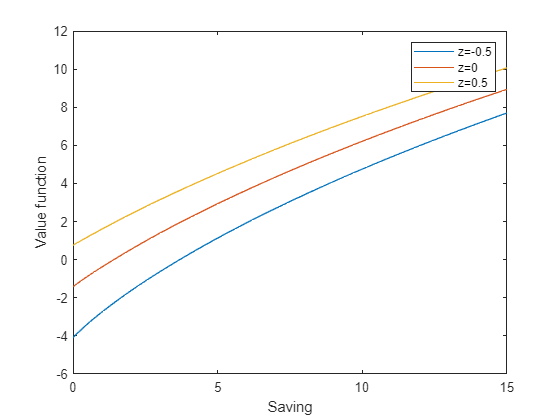

plot(Agrid,Value(:,1),Agrid,Value(:,2),Agrid,Value(:,3))
legend("z=-0.5","z=0","z=0.5")
xlabel("Saving")
ylabel("Value function")

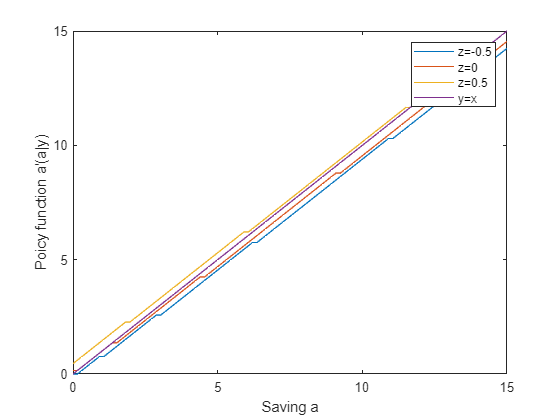

plot(Agrid,Agrid(policy(:,1)),Agrid,Agrid(policy(:,2)),Agrid,Agrid(policy(:,3)),Agrid,Agrid)
legend("z=-0.5","z=0","z=0.5","y=x")
xlabel("Saving a")
ylabel("Poicy function a'(a|y)")

3. Simulate the population with policy function

policy

policy = 100×3
     1     2     4
     1     2     5
     2     3     6
     3     4     7
     4     5     8
     5     6     9
     6     7    10
     6     8    11
     7     9    12
     8    10    13


T

T = 3×3
    0.9000    0.0800    0.0200
    0.1500    0.7000    0.1500
    0.0500    0.1500    0.8000


pop=1000 %sample number

pop = 1000

time=3000 %sample periods

time = 3000

rnd=rand(pop,time); %random number generator, U[0,1]
asimul=zeros(pop,time); %will save as index
ysimul=zeros(pop,time); %will save as index
asimul(:,1)=1;
ysimul(:,1)=2;
Thres=cumsum(T')' %probability given y state

Thres = 3×3
    0.9000    0.9800    1.0000
    0.1500    0.8500    1.0000
    0.0500    0.2000    1.0000


for j=1:time-1
    for i=1:pop
        asimul(i,j+1)=policy(asimul(i,j),ysimul(i,j)); %determined from previous state
        TT=Thres(ysimul(i,j),:);
        if rnd(i,j)>TT(2) % determined from random number, probability given y state
            ysimul(i,j+1)=3;
        elseif rnd(i,j)>TT(1)
            ysimul(i,j+1)=2;
        else
            ysimul(i,j+1)=1;
        end
    end
end
asimul

asimul = 1000×3000
     1     2     1     1     1     1     1     1     1     1     1     1     1     1     1     4     7    10    13    12    10     8     6     5     4     3     2     1     1     1
     1     2     2     2     2     2     2     2     2     5     8    11    14    16    18    20    22    24    26    28    30    32    30    29    28    27    26    28    30    32
     1     2     1     1     1     1     1     1     1     1     2     2     5     8    11    10    10    10    10    10    10    13    11    10    10     8     6     5     4     3
     1     2     2     2     5     8    11    14    16    15    14    13    16    18    17    16    14    12    10     8     6     5     4     3     2     1     2     2     5     8
     1     2     5     8    11    14    16    18    20    22    24    26    23    20    18    16    15    14    16    14    12    10     8     6     5     4     3     2     1     1
     1     2     2     2     2     2     5     4     3     2     1     1    

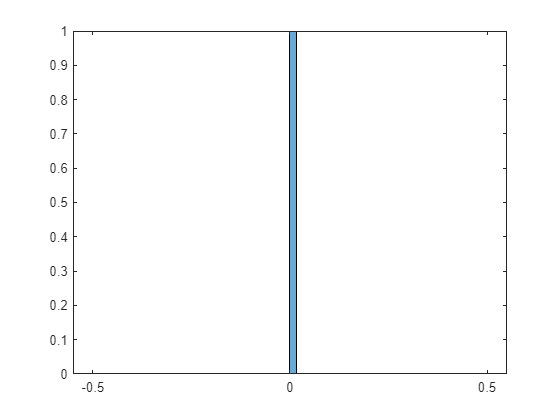

c=histogram(Agrid(asimul(:,1)),60); %t=1
c.Normalization = 'probability';

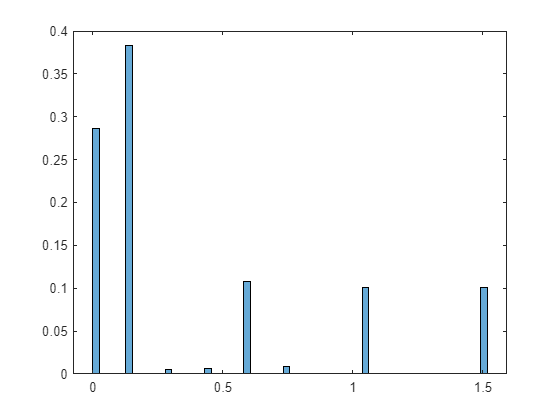

c=histogram(Agrid(asimul(:,5)),60); %t=5
c.Normalization = 'probability';

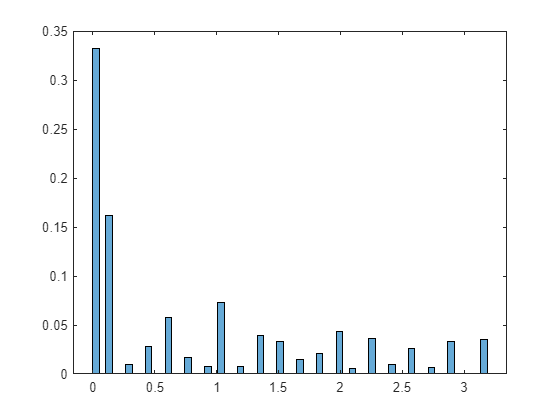

c=histogram(Agrid(asimul(:,10)),60); %t=10
c.Normalization = 'probability';

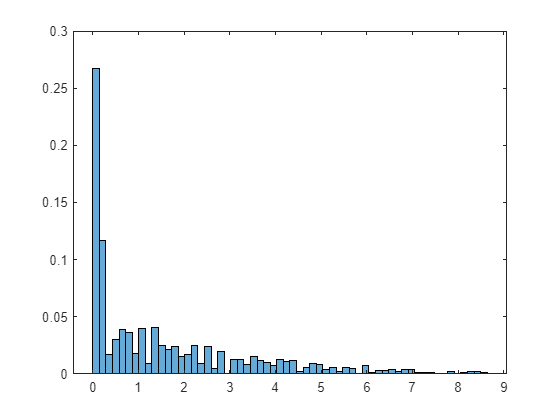

c=histogram(Agrid(asimul(:,100)),60); %t=100
c.Normalization = 'probability';

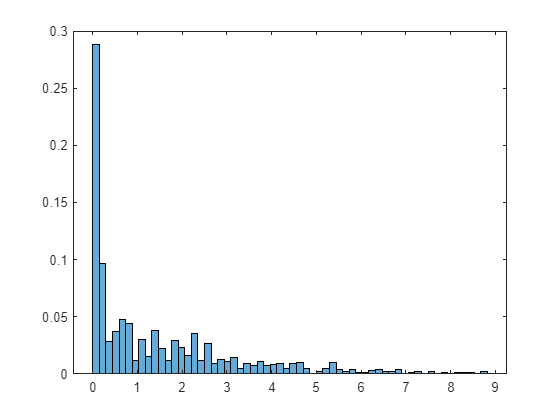

c=histogram(Agrid(asimul(:,2000)),60); %t=2000
c.Normalization = 'probability';

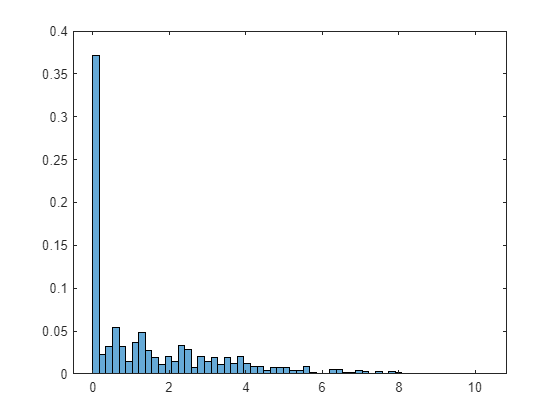

c=histogram(Agrid(asimul(:,2500)),60); %t=2500
c.Normalization = 'probability';

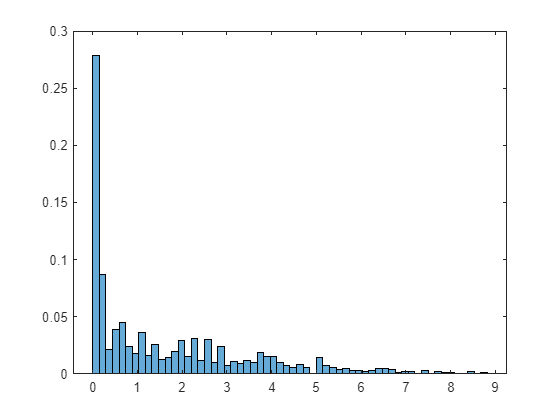

c=histogram(Agrid(asimul(:,3000)),60); %t=3000
c.Normalization = 'probability';

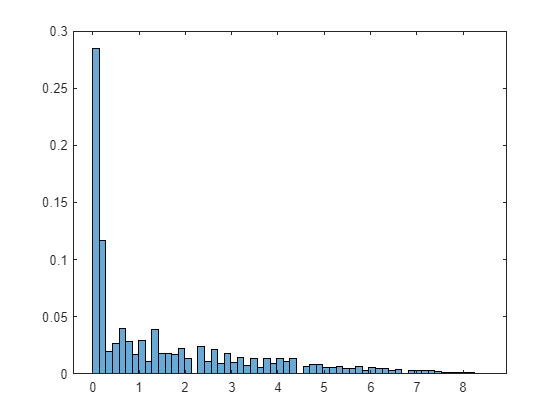

c=histogram(Agrid(asimul(1,:)),60); %one person
c.Normalization = 'probability';

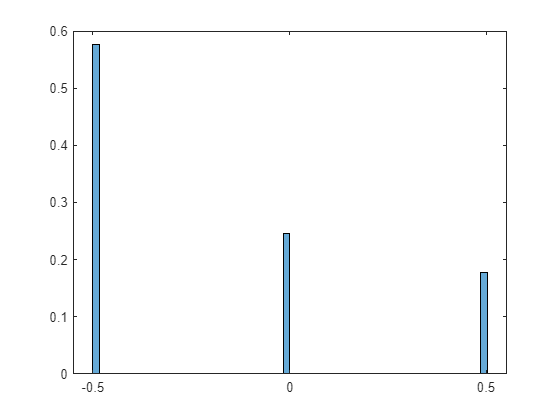

c=histogram(Ygrid(ysimul(3,:)),60); 
c.Normalization = 'probability';

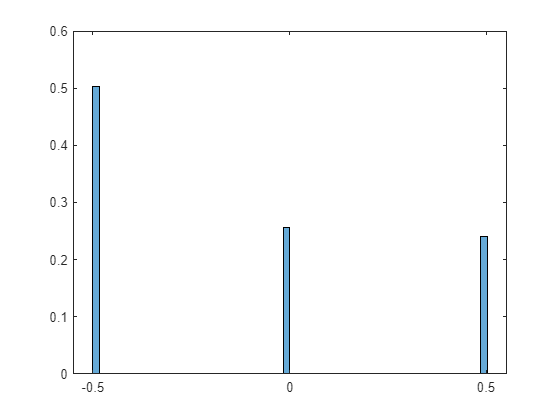

c=histogram(Ygrid(ysimul(:,:)),60); 
c.Normalization = 'probability';

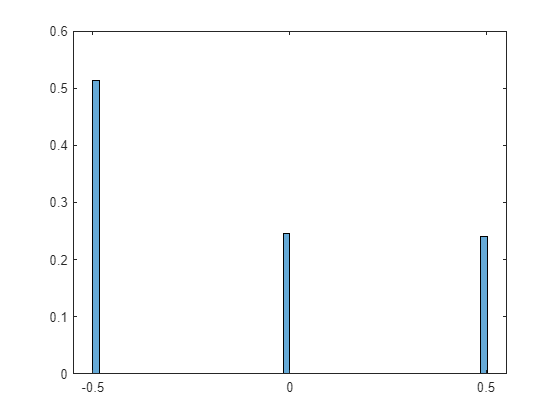

c=histogram(Ygrid(ysimul(:,2000)),60); 
c.Normalization = 'probability';